clc; clear; close all;
rng(42); % Semilla para reproducibilidad
load('digits.mat');
[num_pixels, num_samples] = size(digits.image); % 784 x 10000

fprintf('\n--- Comparación de PCA con distintas dimensiones ---\n');


--- Comparación de PCA con distintas dimensiones ---


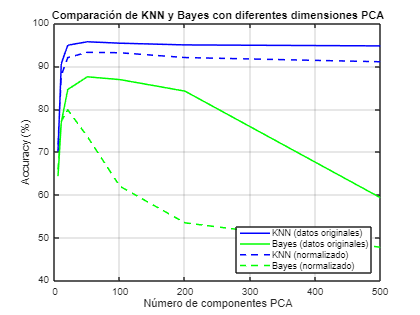


% Dividir datos (90% train, 10% test)
num_train = round(0.8 * num_samples);
indices = randperm(num_samples);
train_idx = indices(1:num_train);
test_idx = indices(num_train+1:end);

% Normalización (media 0, varianza 1)
mean_img = mean(digits.image, 2);
std_img = std(digits.image, 0, 2);
image_norm = (digits.image - mean_img) ./ (std_img + eps);

% Dimensiones a probar
dims = [5, 10, 20, 50, 100, 200, 500];
num_dims = length(dims);

% Inicializar resultados
acc_knn_no = zeros(1, num_dims);
acc_bayes_no = zeros(1, num_dims);
acc_knn_norm = zeros(1, num_dims);
acc_bayes_norm = zeros(1, num_dims);

% PCA para no normalizado
[coeff_no, score_no] = pca(digits.image');
% PCA para normalizado
[coeff_norm, score_norm] = pca(image_norm');

% Configuración de validación cruzada
cv = cvpartition(num_samples, 'KFold', 5);  % 5 pliegues de validación cruzada

% Loop sobre dimensiones
for i = 1:num_dims
    d = dims(i);

    % Sin normalizar
    X_no = score_no(:, 1:d);
    Y = digits.label';

    % KNN con validación cruzada
    cv_knn_no = crossval(@(Xtrain, Ytrain, Xtest, Ytest) ...
        mean(predict(fitcknn(Xtrain, Ytrain, 'NumNeighbors', 3), Xtest) == Ytest) * 100, ...
        X_no, Y, 'Partition', cv);
    acc_knn_no(i) = mean(cv_knn_no);

    % Bayes con validación cruzada
    cv_bayes_no = crossval(@(Xtrain, Ytrain, Xtest, Ytest) ...
        mean(predict(fitcnb(Xtrain, Ytrain), Xtest) == Ytest) * 100, ...
        X_no, Y, 'Partition', cv);
    acc_bayes_no(i) = mean(cv_bayes_no);

    % Normalizado
    X_norm = score_norm(:, 1:d);

    % KNN con validación cruzada
    cv_knn_norm = crossval(@(Xtrain, Ytrain, Xtest, Ytest) ...
        mean(predict(fitcknn(Xtrain, Ytrain, 'NumNeighbors', 3), Xtest) == Ytest) * 100, ...
        X_norm, Y, 'Partition', cv);
    acc_knn_norm(i) = mean(cv_knn_norm);

    % Bayes con validación cruzada
    cv_bayes_norm = crossval(@(Xtrain, Ytrain, Xtest, Ytest) ...
        mean(predict(fitcnb(Xtrain, Ytrain), Xtest) == Ytest) * 100, ...
        X_norm, Y, 'Partition', cv);
    acc_bayes_norm(i) = mean(cv_bayes_norm);
end

% ---------- Graficar resultados ----------
figure;

% Graficar con estilos específicos
plot(dims, acc_knn_no, '-', 'Color', 'blue', 'LineWidth', 1.5); hold on;
plot(dims, acc_bayes_no, '-', 'Color', 'green', 'LineWidth', 1.5);
plot(dims, acc_knn_norm, '--', 'Color', 'blue', 'LineWidth', 1.5);
plot(dims, acc_bayes_norm, '--', 'Color', 'green', 'LineWidth', 1.5);

% Configuración de ejes y leyenda
xlabel('Número de componentes PCA');
ylabel('Accuracy (%)');
title('Comparación de KNN y Bayes con diferentes dimensiones PCA');
legend('KNN (datos originales)', 'Bayes (datos originales)', ...
       'KNN (normalizado)', 'Bayes (normalizado)', ...
       'Location', 'southeast');
grid on;